# TP #09 - Ejercicio 09

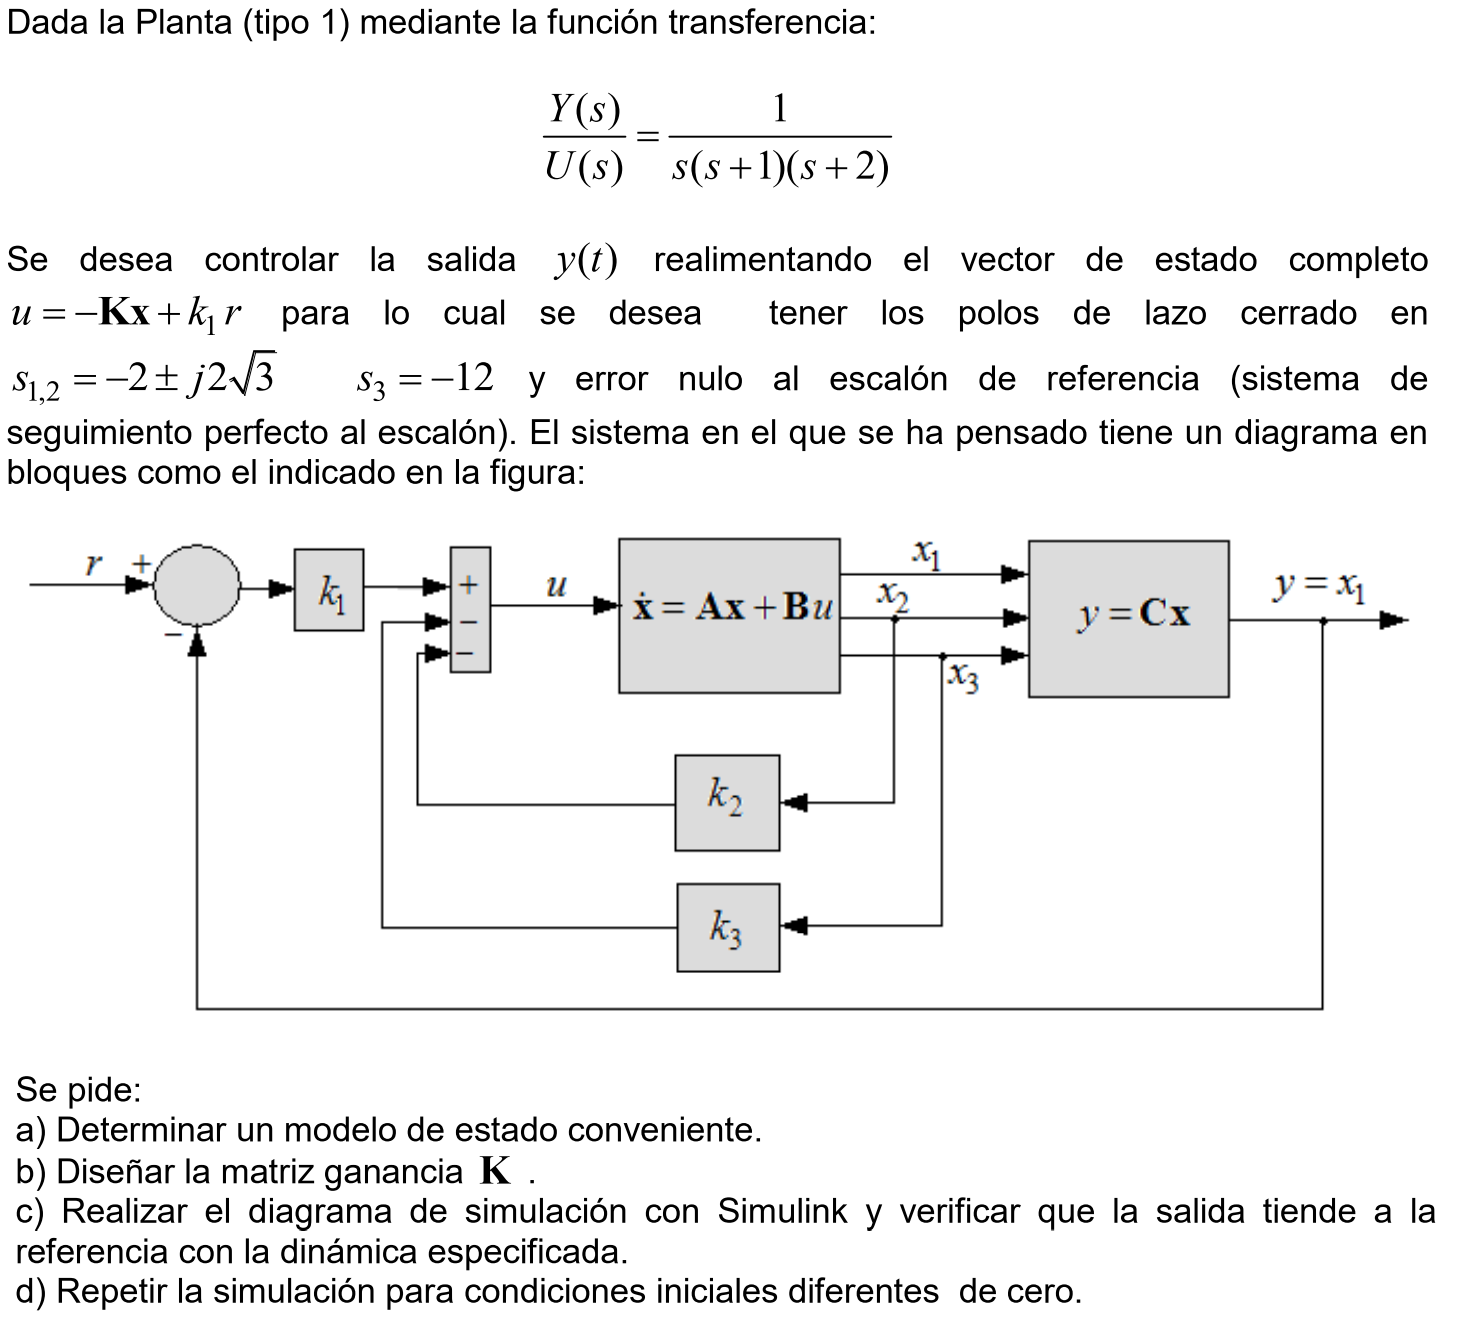

Del enunciado


$$\begin{array}{l}
G\left(s\right)=\frac{1}{\left(s+1\right)\;\left(s+2\right)\;s\;}\\
G\left(s\right)=\frac{1}{\left(s^2 +3s+2\right)s}\\
G\left(s\right)\;=\frac{1}{s^3 +s^2 \;3+s\;2}
\end{array}$$


En base al modelo canónico controlable podemos definir,


$$\left\lbrack A\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-a_0  & {-a}_1  & {-a}_2 
\end{array}\right\rbrack$$



$$\left\lbrack A\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
0 & -2 & -3
\end{array}\right\rbrack$$



$$\left\lbrack B\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$$



$$\left\lbrack C\right\rbrack =\left\lbrack \begin{array}{ccc}
\left(b_0 -b_3 a_0 \right) & \left(b_1 -b_3 a_1 \right) & \left(b_2 -b_3 a_2 \right)
\end{array}\right\rbrack$$



$$\left\lbrack C\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack$$



$$\left\lbrack D\right\rbrack =\left\lbrack b_3 \right\rbrack$$



$$\left\lbrack D\right\rbrack =\left\lbrack 0\right\rbrack$$


Del gráfico


$$\begin{array}{l}
\mu \left(t\right)=\left(r\left(t\right)-x_1 \left(t\right)\right)k_1 -x_2 \left(t\right)k_2 -x_3 \left(t\right)k_3 \\
\mu \left(t\right)=r\left(t\right)k_1 -x_1 \left(t\right)k_1 -x_2 \left(t\right)k_2 -x_3 \left(t\right)k_3 \\
\mu \left(t\right)=r\left(t\right)k_1 -K\;X\left(t\right)\\
\overset{\ldotp }{X} \left(t\right)=A\;X\left(t\right)+B\mu \left(t\right)\\
\overset{\ldotp }{X} \left(t\right)=A\;X\left(t\right)+B\left(r\left(t\right)k_1 -K\;X\left(t\right)\right)\\
\overset{\ldotp }{X} \left(t\right)=\left(A-B\;K\right)X\left(t\right)+B\;r\left(t\right)k_1 
\end{array}$$


Quedando entonces,


$$\begin{array}{l}
A-\textrm{BK}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
0 & -2 & -3
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
k_1  & k_2  & k_3 
\end{array}\right\rbrack \\
A-\textrm{BK}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
0 & -2 & -3
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
k_1  & k_2  & k_3 
\end{array}\right\rbrack \\
A-\textrm{BK}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-k_1  & -2-k_2  & -3{-k}_3 
\end{array}\right\rbrack 
\end{array}$$


Finalmente hallamos la expresión de los polos deseados,


$$\begin{array}{l}
\left(\textrm{sI}-A+\textrm{BK}\right)=\left\lbrack \begin{array}{ccc}
s & 0 & 0\\
0 & s & 0\\
0 & 0 & s
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-k_1  & -2-k_2  & -3{-k}_3 
\end{array}\right\rbrack \\
\left(\textrm{sI}-A+\textrm{BK}\right)=\left\lbrack \begin{array}{ccc}
s & -1 & 0\\
0 & s & -1\\
k_1  & 2+k_2  & s+3+k_3 
\end{array}\right\rbrack 
\end{array}$$


Hallamos ahora el determinante,

$\textrm{det}\left(\textrm{sI}-A+\textrm{BK}\right)=s^3 +s^2 \;\left(3+k_3 \right)+s\;\left(2+k_2 \right)+k_1$; **(a)**

Del enunciado sabemos que los polos a lazo cerrado se desean en,


$$\begin{array}{l}
\textrm{PLC}:\;\left(s+2+\textrm{j2}\sqrt{3}\right)\;\left(s+2+\textrm{j2}\sqrt{3}\right)\;\left(s+12\right)\;\\
\textrm{PLC}:\;\left(s^2 +4s+16\right)\left(s+12\right)\\
{\textrm{PLC}:\;s}^3 +s^2 \;16+s\;64+192
\end{array}$$


Reemplazando estos valores en **(a)** obtenemos,

- 
$$k_1 =192$$


- 
$$k_2 =62$$


- 
$$k_3 =13$$


Podemos además corroborar con la función 'acker'

A = [0 1 0; 0 0 1; 0 -2 -3];
B = [0; 0; 1];
C = eye(3);
PLC=[-2+(2*sqrt(3))*i -2-(2*sqrt(3))*i -12];
disp('Ganancias calculadas con Ackerman:')

Ganancias calculadas con Ackerman:


K=acker(A,B,PLC)

K =   192.0000   62.0000   13.0000


disp('Vector de Realimentción de Estados ([An]):')

Vector de Realimentción de Estados ([An]):


An=A-B*K

An =          0    1.0000         0
         0         0    1.0000
 -192.0000  -64.0000  -16.0000


disp('Posición diseñada de los polos a lazo cerrado:')

Posición diseñada de los polos a lazo cerrado:


PLC_d=eig(An)

PLC_d =   -2.0000 + 3.4641i
  -2.0000 - 3.4641i
 -12.0000 + 0.0000i


Simulink, ejecutar ***TP09_ej09.slx.***